imagens = imageDatastore('C:\Users\PF\Documents\treino','IncludeSubfolders',true,'LabelSource','foldernames','FileExtensions',{'.jpg'});

[trainingImages, valImages ,testImages] = splitEachLabel (imagens, 0.6,0.2,0.2,'randomize');

cnn = alexnet;

layers = cnn.Layers 

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    

%net.Layers
%substitui a camadas 23 por outra camada totalmente conectada, com 2 labels (foco e sem foco). 
layers(23) = fullyConnectedLayer(2);
%substitui a camada 25 por outra camada de classificação.
layers(25) = classificationLayer;

The first layer, the image input layer, requires input images of size 227-by-227-by-3, where 3 is the number of color channels. 

%inputSize = net.Layers(1).InputSize
inputSize = cnn.Layers(1).InputSize

inputSize =    227   227     3


pixelRange = [-30 30];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange);

augimdsTrain = augmentedImageDatastore(inputSize,trainingImages, ...
    'DataAugmentation',imageAugmenter);

augimdsValidation = augmentedImageDatastore(inputSize,valImages);


options = trainingOptions('sgdm', ...
    'MiniBatchSize',64, ...
    'MaxEpochs',20, ...
    'InitialLearnRate',0.001, ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',50, ...
    'ValidationPatience',Inf, ...
    'Verbose',false, ...
    'Plots','training-progress');

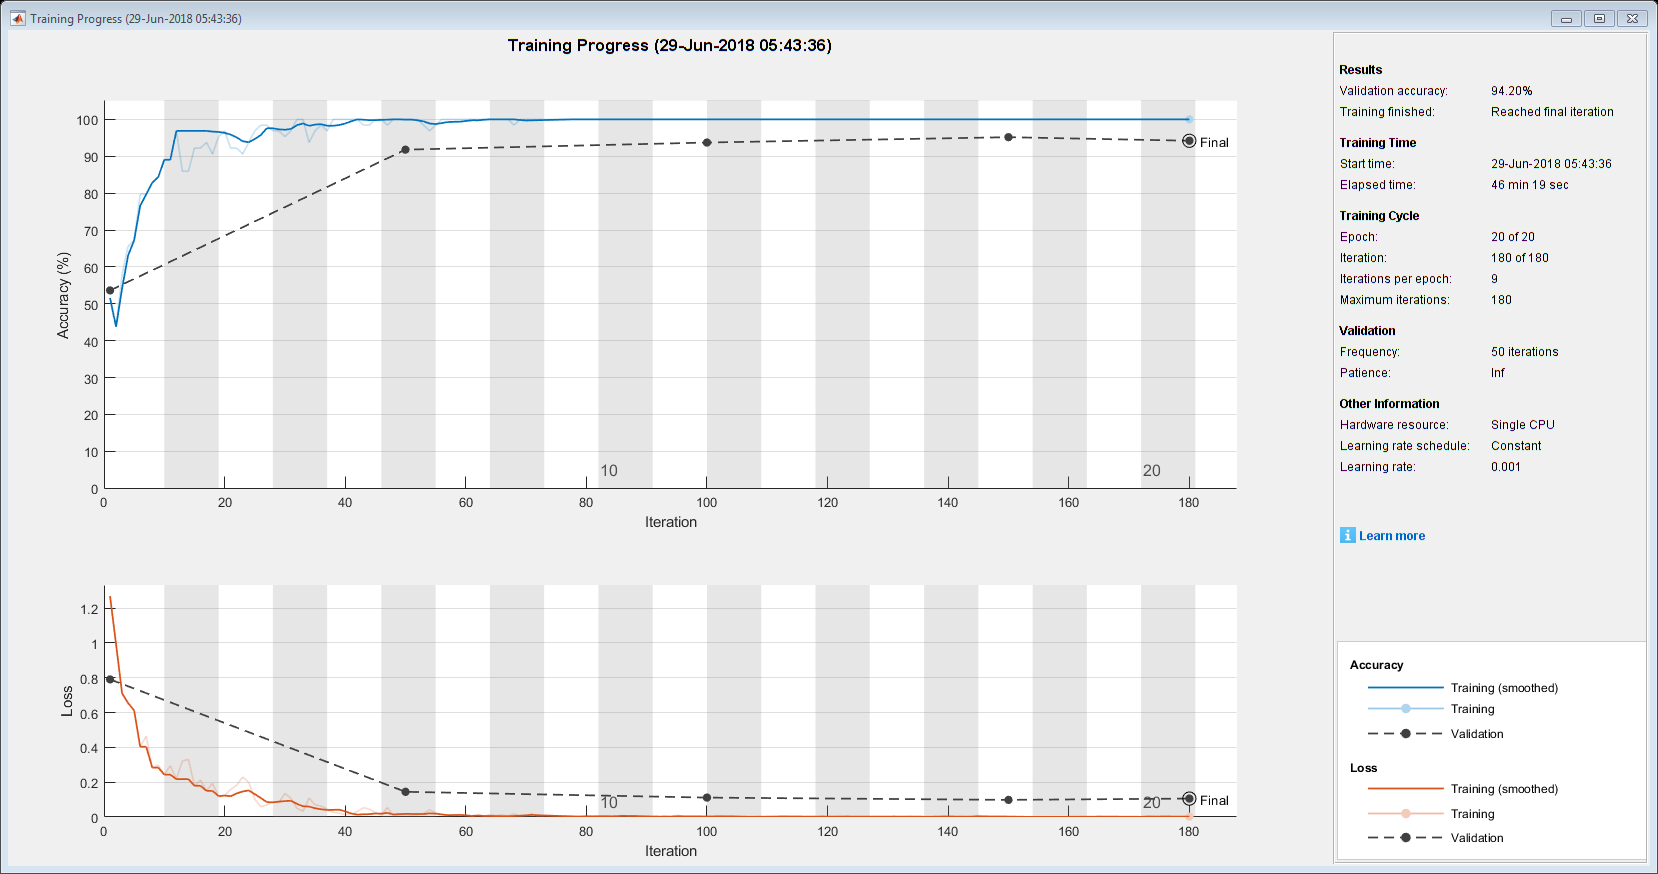

rede = trainNetwork(trainingImages, layers, options);

  predictedLabels = classify(rede, testImages); 



accuracy = mean(predictedLabels == testImages.Labels)

accuracy = 0.9663